**用于从data文件->反解->muap（100个点）->CoG(可能需要补充通道)->CoG的分布的实验**

1. 批量从otb转到m文件(用trigger的话),没trigger的话直接biolab处理

clear;
close all;
addpath (genpath ('Z:\code'));
filePath = 'Z:\data\24-10-13iEMG-sEMG';%%%%%%%%需要修改
cd(filePath);
fileNames = dir('*.otb+');
for i = 1:length(fileNames)
    tmpName = fileNames(i).name;
    fullPath = [fileNames(i).folder '/' fileNames(i).name];
    data = OpenOTBfilesBatch(fullPath);

    trigger=data(65,:);%%%%%%%%%%%%%%%%%%%%%需要修改
    tmpInd = find(trigger>3400);
    tmpInd(find(diff(tmpInd)<=5)+1) = [];
    % if contains(tmpName,'M1')
    %     chInd = 9;
    % else
    %     chInd = [9,17:80];
    % end
    chInd = 1:64;%%%%%%%%%%%%%%%%%%%%%%%%%%%%需要修改

    %保存
    data_EMG = data(chInd,tmpInd(1):tmpInd(2));
    %         figure; plotsig_cc(data_EMG,10240);
    save([fullPath(1:end-5) '.mat'],'data_EMG');
    % end
end

2.反解（用trigger的话是data_EMG,不用是Data{1}）

 
level=1;
for trial=1:3
    % path_fold='Z:\data\24-10-13iEMG-sEMG';
    path_fold='Z:\data\24-10-13iEMG-sEMG';
    % path_semg=[path_fold '\M2L' num2str(level) 'T'  num2str(trial) '.mat'];
    path_semg=[path_fold '\M1L1T'  num2str(trial) '.mat'];
    load(path_semg);

    data_sEMG=double(Data{1})';%otb
    % data_sEMG=data_EMG;%XML
    % data_sEMG=double(data_sEMG(2:65,:));%%%%%%% need if 采集频率single
    % data_sEMG=downsample(data_sEMG',5)';%%%%%%% need if 采集频率10240Hz
    % data_sEMG=semgd;
    fsamp = 2048;

    decoderParameters.fsamp = fsamp;
    decoderParameters.TimeDifference = 0;
    decoderParameters.SpatialDifference = 0;
    %13--5*13; 18--mouvi8*8  5--紫色QT8*8 %%%需要注意电极片位置
    decoderParameters.ElectrodeType = 18;
    decoderParameters.BandpassFilter = 1;%20-500Hz带通滤波
    decoderParameters.LineFilter = 1;%50Hz梳状滤波
    decoderParameters.ChannelFilter = 1;%去除不好的电极channel
    decoderParameters.extendingFactor = 10;%论文里是10c
    decoderParameters.costFcn = 3;
    decoderParameters.iterationNumW = 45;%45
    decoderParameters.iterationNumMU = 30;

    [decompData,dataarray,datafilt,prohibitInd,decompChannelInd] = PreProcess4GUI_v2(data_sEMG,decoderParameters);
    decomps = IPTExtraction_gCKC4GUI_v3(decompData,decoderParameters); % classic gradient CKC

    CKCdecomp{level,trial}=decomps;
    CKCdecomp{level,trial}.datafilt=datafilt;
    CKCdecomp{level,trial}.prohibitInd=prohibitInd;
end

    Spike extraction ...
    Removing duplications: configuration of duplication elimination: exp. ...
36.3034 s 
    Spike extraction ...
    Removing duplications: configuration of duplication elimination: exp. ...
38.2554 s 
    Spike extraction ...
    Removing duplications: configuration of duplication elimination: exp. ...
34.8102 s 


saveflag=0;
savepath='Z:\Result\24-10-13iEMG-sEMG\1013_sEMG_CKC_first.mat' ;
if saveflag
    save(savepath,"CKCdecomp");
end

clearvars -except CKCdecomp%清除变量，只留CKCdecomp

3.得到所有的muap，同时看是否有通道被prohibited，为cog准备

 
level=1;
for trial=1:3
    decomps=0;
    %%%将muapt赋予到old中
    decomps=CKCdecomp{level,trial};%CKC
    old=decomps.MUPulses;          %CKC
    %放电频率
    fsamp=2048;
    %计算muap
    datafilt=decomps.datafilt;
    [sigcell]=sig2cell(datafilt,6);%对5*13数据
    [muaparray,~]=muapExtraction(sigcell,old,100,'STA');
    muaparraycell{trial}=muaparray;%得到所有MUAParray
end

3.2绘制放电串

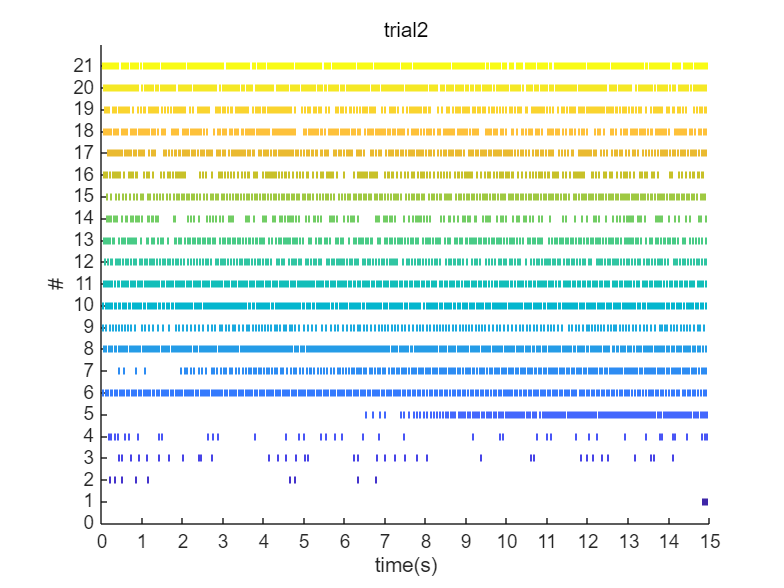

trial=2;
decomps=CKCdecomp{level,trial};%CKC
old=decomps.MUPulses;          %CKC
numPT=length(old);
figure;clf;pic=draw_PluseTime(old,fsamp,1);%PT
title(['trial' num2str(trial)])

3.3绘制MUAP（记录有问题的电极）

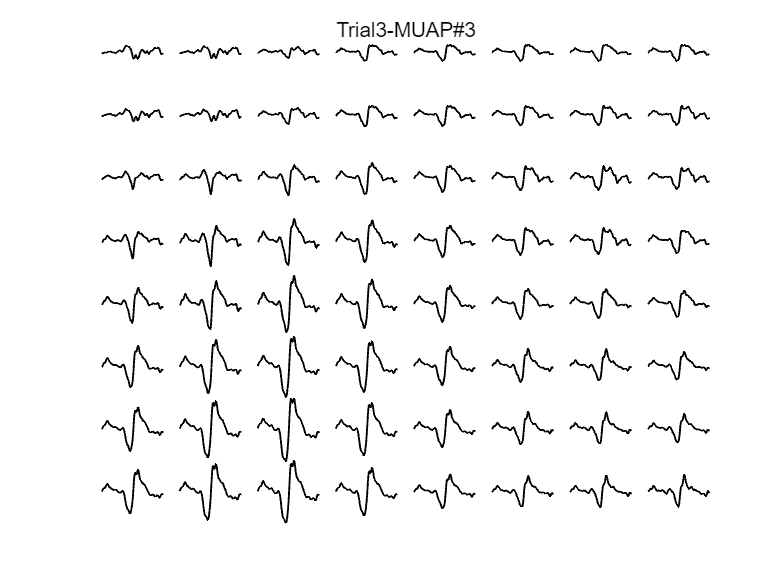

trial=3;which2show=3;
clf;
muap_recon=muap_pca(muaparraycell{trial}{which2show},0.95);
figure;
plotArrayPotential(muap_recon,1,1);%muap
tn4AP=['Trial' num2str(trial) '-MUAP#' num2str(which2show)];
title(tn4AP);

4.CoG整体绘制，给出分布图

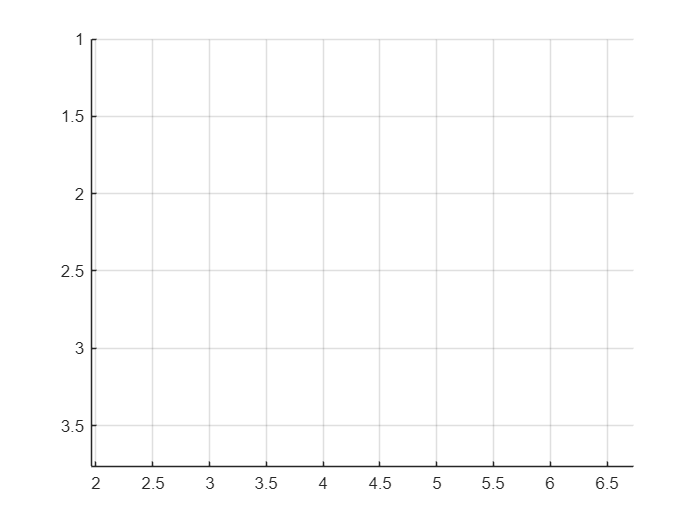

 
k=1;
cogall={};
for trial=1:1
    % muaparray={};
    % muaparray=muaparraycell{trial};
    for num=1:1:length(muaparray)

        muap=muaparray{num};
        muap_recon=muap_pca(muap,0.95);

        muap_cog=muap_recon;
        %%%%若有电极有问题，进行插值
        % muap_cog{1,1}=(muap_cog{2,1}+muap_cog{2,2}+muap_cog{1,2})/3;
% muap_cog{3,3}=(muap_cog{2,2}+muap_cog{3,2}+muap_cog{4,2}+muap_cog{2,3}+muap_cog{2,4}+muap_cog{3,4}+muap_cog{4,4})/8;
        % muap_cog{5,2}=(muap_cog{5,1}+muap_cog{4,2}+muap_cog{5,3}+muap_cog{4,1}+muap_cog{4,3}+muap_cog{6,1}+muap_cog{6,3})/7;
        % muap_cog{6,2}=(muap_cog{6,1}+muap_cog{5,1}+muap_cog{7,1}+muap_cog{7,2}+muap_cog{5,3}+muap_cog{6,3}+muap_cog{7,3})/7;

        % muap_cog{10,3}=(muap_cog{9,2}+muap_cog{10,2}+muap_cog{11,2}+muap_cog{9,4}+muap_cog{10,4}+muap_cog{11,4}+muap_cog{9,3}+muap_cog{11,3})/8;

        % muap_cog{13,1}=(muap_cog{13,2}+muap_cog{12,2}+muap_cog{12,1})/3;

        [iend,jend]=size(muap_recon);
        for i=1:1:iend
            for j=1:1:jend
                if i+j==2%%%%%%%%%%%%%%%%%%%%%for5*13
                    tmpmuap=(muap_cog{2,1}+muap_cog{2,2}+muap_cog{1,2})/3;
                else
                     tmpmuap=muap_cog{i,j};
                end
                % tmpmuap=muap_cog{i,j};
                p2p(i,j)=max(tmpmuap)-min(tmpmuap);
            end
        end
        % p2p=normalize(p2p(2:13,:));
        max_peak=max(max(p2p));
        min_peak=min(min(p2p));
        for i=1:1:iend
            for j=1:1:jend
                p2p_norm(i,j)=(p2p(i,j)-min_peak)/(max_peak-min_peak);
            end
        end

        %CoG from Xia
        for i=1:1:iend
            for j=1:1:jend
                if p2p_norm(i,j)>0.8
                    p2p_cog(i,j)=p2p_norm(i,j);%cog不用0.8以下的值
                else
                    p2p_cog(i,j)=0;
                end
            end
        end

        P=sum(sum(p2p_cog));
        cogx=0;
        cogy=0;
        for i=1:1:iend
            for j=1:1:jend
                cogx=cogx+p2p_cog(i,j)*j;
                cogy=cogy+p2p_cog(i,j)*i;
            end
        end
        cogx=cogx/P;
        cogy=cogy/P;
        cogall{trial}(k,:)=[cogx,cogy];
        k=k+1;
    end
end
cogmat=[];
for i=1:1%%%%%%%%%%%%%%%%%%%%%%%%%%trial数
    cogmat=[cogmat;cogall{i}];
end
figure;
scatter(cogmat(:,1),cogmat(:,2));hold on
xlim([1,8]);ylim([1,8]);
% 循环遍历每个数据点，并添加序号
for i = 1:size(cogmat,1)
    text(cogmat(i,1),cogmat(i,2), num2str(i), 'FontSize', 10); % 在每个点旁边添加序号
end

set(gca, 'YDir', 'reverse');
grid on

找出在扎入点附件的PT

idx=cogmat(:,1) >= 3 & cogmat(:,1) <= 5 & cogmat(:,2) >= 3 & cogmat(:,2) <= 5;
find(idx==1)


ans =

  空的 0×1 double 列向量



% idx=(cogmat(:,1) >= 3 &_cogmat(:,1) <=5) && (cogmat(:,2) >=3 &_cogmat(:,2)<=5)

5.Cog单独查看

trial=1;num=1;
% muaparray={};
% muaparray=muaparraycell{trial};


muap=muaparray{num};
muap_recon=muap_pca(muap,0.95);

muap_cog=muap_recon;
%%%%若有电极有问题，进行插值
% muap_cog{1,1}=(muap_cog{2,1}+muap_cog{2,2}+muap_cog{1,2})/3;

% muap_cog{3,3}=(muap_cog{2,2}+muap_cog{3,2}+muap_cog{4,2}+muap_cog{2,3}+muap_cog{2,4}+muap_cog{3,4}+muap_cog{4,4})/8;
% muap_cog{6,2}=(muap_cog{6,1}+muap_cog{5,1}+muap_cog{7,1}+muap_cog{7,2}+muap_cog{5,3}+muap_cog{6,3}+muap_cog{7,3})/7;

% muap_cog{10,3}=(muap_cog{9,2}+muap_cog{10,2}+muap_cog{11,2}+muap_cog{9,4}+muap_cog{10,4}+muap_cog{11,4}+muap_cog{9,3}+muap_cog{11,3})/8;

% muap_cog{13,1}=(muap_cog{13,2}+muap_cog{12,2}+muap_cog{12,1})/3;

[iend,jend]=size(muap_recon);
for i=1:1:iend
    for j=1:1:jend
        if i+j==2%%%%%%%%%%%%%%%%%%%%%for5*13
            tmpmuap=(muap_cog{2,1}+muap_cog{2,2}+muap_cog{1,2})/3;
        else
             tmpmuap=muap_cog{i,j};
        end
        % tmpmuap=muap_cog{i,j};
        p2p(i,j)=max(tmpmuap)-min(tmpmuap);
    end
end
% p2p=normalize(p2p(2:13,:));
max_peak=max(max(p2p));
min_peak=min(min(p2p));
for i=1:1:iend
    for j=1:1:jend
        p2p_norm(i,j)=(p2p(i,j)-min_peak)/(max_peak-min_peak);
    end
end

%CoG from Xia
for i=1:1:iend
    for j=1:1:jend
        if p2p_norm(i,j)>0.8
            p2p_cog(i,j)=p2p_norm(i,j);%cog不用0.8以下的值
        else
            p2p_cog(i,j)=0;
        end
    end
end

P=sum(sum(p2p_cog));
cogx=0;
cogy=0;
for i=1:1:iend
    for j=1:1:jend
        cogx=cogx+p2p_cog(i,j)*j;
        cogy=cogy+p2p_cog(i,j)*i;
    end
end
cogx=cogx/P;
cogy=cogy/P;
cogall{trial}(k,:)=[cogx,cogy];



%绘制曲面与等线图
f2=figure;
step=0.1;
x=1:iend; y=1:jend; [x,y]=meshgrid(x,y);
x_i=1:step:iend;y_i=1:step:jend;
[xi,yi]=meshgrid(x_i,y_i);
zi=interp2(x,y,p2p_norm,xi,yi,"cubic");

错误使用 griddedInterpolant
GridVectors 必须定义大小与 Values 数组兼容的网格。

出错 interp2>makegriddedinterp (第 226 行)
    F = griddedInterpolant(varargin{:});

出错 interp2 (第 134 行)
        F = makegriddedinterp(X, Y, V, method,extrap);

% zzi=interp2(x,y,p2p_cog,xi,yi,"nearest");
% surfc(xi,yi,zzi)
imagesc(x_i,y_i,zi);
set(gca,'YTick',[1:1:iend])
set(gca,'XTick',[1:1:jend])

colormap("jet")
hold on
scatter(cogx,cogy,'green','o','filled')
plotArrayPotential(muap_cog,1,1);
title(['#' num2str(num) '(' num2str(cogx) ',' num2str(cogy) ')'])
f3=figure;

surfc(xi,yi,zi)
shading interp
set(gca,'YTick',[1:1:iend])
set(gca,'XTick',[1:1:jend])
colormap("jet")
colorbar

hold on
% zzi=zi;
% imagesc(x_i,y_i,zzi)
scatter(cogx,cogy,'black','x')